# Kalman Filter Workshop Exercise #1: Linear Kalman Filters

In this exercise, you will interactively design a linear Kalman filter to estimate the angular position of a simple pendulum.

## Simulate Pendulum Motion 

In this exercise, you will use this Simulink model (shown below) that contains a simple pendulum modeled to calculate actual and measured system responses. First, **run this section** to specify parameters for the model and open the model.

Ts = 0.01;      % Simulation fixed step size [s]
m = 1;          % Pendulum mass [kg]
L = 0.5;        % Pendulum length [m]
theta0 = pi/18; % Pendulum initial position [rad] 
theta_dot0 = 0; % Pendulum initial velocity [rad/s]
g = 9.81;       % Gravity [m/s^2]
open_system pendulum_model

In the model, the pendulum takes two inputs, the driving torque $T$ and the process noise $w$ acting on the pendulum. The pendulum output is its angular position $\theta$. Initially, the process noise is set to zero. The pendulum model does not include friction, which allows perpetual oscillation when the pendulum is displaced from its equilibrium position. 

**Run the simulation** to observe measured and actual pendulum responses using the Data Inspector. 

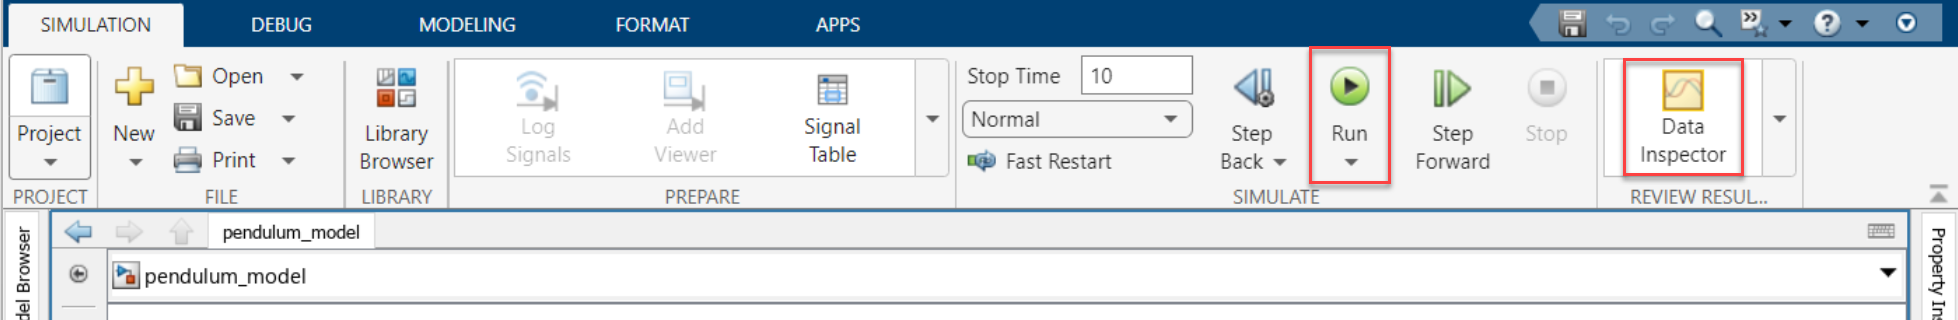

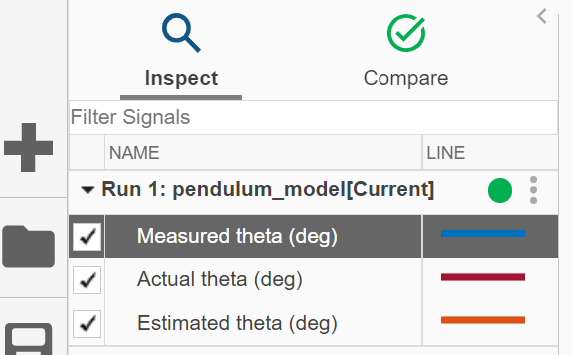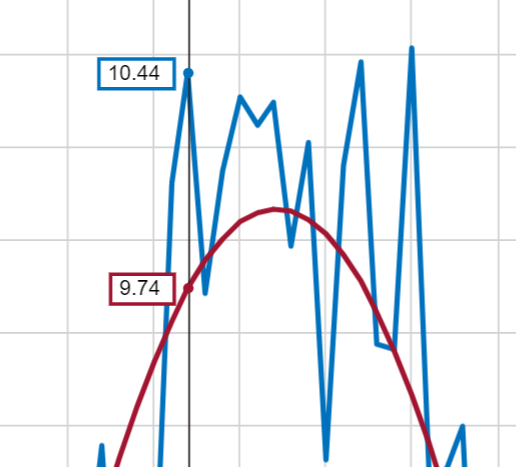

You can also run a simulation from a MATLAB script using the [`sim`](https://www.mathworks.com/help/simulink/slref/sim.html) function. 

out = sim("pendulum_model.slx");
figure;
hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
xlabel('Time [s]'); ylabel('Angular position [°]');
legend("Actual Response","Measured Response","Location","southoutside");
title("Pendulum Motion")
hold off;

Or, you can display saved simulation results in the Data Inspector. After running this section, look for the run named "virtualPendulumModel" in the Data Inspector.

open("Measured_and_actual_responses.mldatx")

## Add a Kalman Filter to Estimate Pendulum Angular Position

A Kalman filter computes the optimal state estimates of a linear plant model described by the state and measurement equations: 


$$\begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}+w\\
y=\textrm{Cx}+\textrm{Du}+v
\end{array}$$


In the equations, $\mathit{\mathbf{w}}$ and $\mathit{\mathbf{v}}$ represent the process and measurement noise, respectively. The random variables $\mathit{\mathbf{w}}$ and $\mathit{\mathbf{v}}$ are assumed to be independent, white and have normal distributions, $\mathit{\mathbf{p}}\left(\mathit{\mathbf{w}}\right)~\mathit{\mathbf{N}}\left(0,\mathit{\mathbf{Q}}\right)$ and $\mathit{\mathbf{p}}\left(\mathit{\mathbf{v}}\right)~\mathit{\mathbf{N}}\left(0,\mathit{\mathbf{R}}\right)$, where $\mathit{\mathbf{Q}}$ and $\mathit{\mathbf{R}}$ are process noise and measurement noise covariances, respectively. 

Uncomment the below line of code to open the supplemental live script for more details on how you can derive the pendulum's equation of motion and create a state space representation.

% open LinearKFSupplemental.mlx

**Run this section **to define the state space matrices derived in the supplemental live script for the linearized pendulum model. This state space representation will be used by our Kalman filter block in Simulink.

A = [0 1; -g/L 0];
B = [0; 1/(m*L^2)];
C = [1 0];
D = 0;

Using the pendulum model from previous exercise, complete the following steps to implement a linear Kalman filter.

- **Add a **[**Kalman Filter**](https://www.mathworks.com/help/control/ref/kalmanfilter.html)** block** from the Control System Toolbox > State Estimation library. The block takes known inputs $u$ and measurements $y$ and computes the state estimates $\textrm{xhat}$. 

- For the Kalman Filter block, **connect the input torque signal **$\mathit{\mathbf{T}}$** to input port **$\mathit{\mathbf{u}}$, and **measured theta signal to input port **$\mathit{\mathbf{y}}$. 

- For the Kalman Filter block, **connect the **$\textrm{xhat}$** outport to the Selector block**. The state estimates computed by the Kalman filter, $\textrm{xhat}$, are a 2x1 vector containing estimates of $\theta$ and $\dot{\theta}$.  The selector block will select and feed the estimated $\theta$ to the R2D conversion block to be displayed in the Scope.

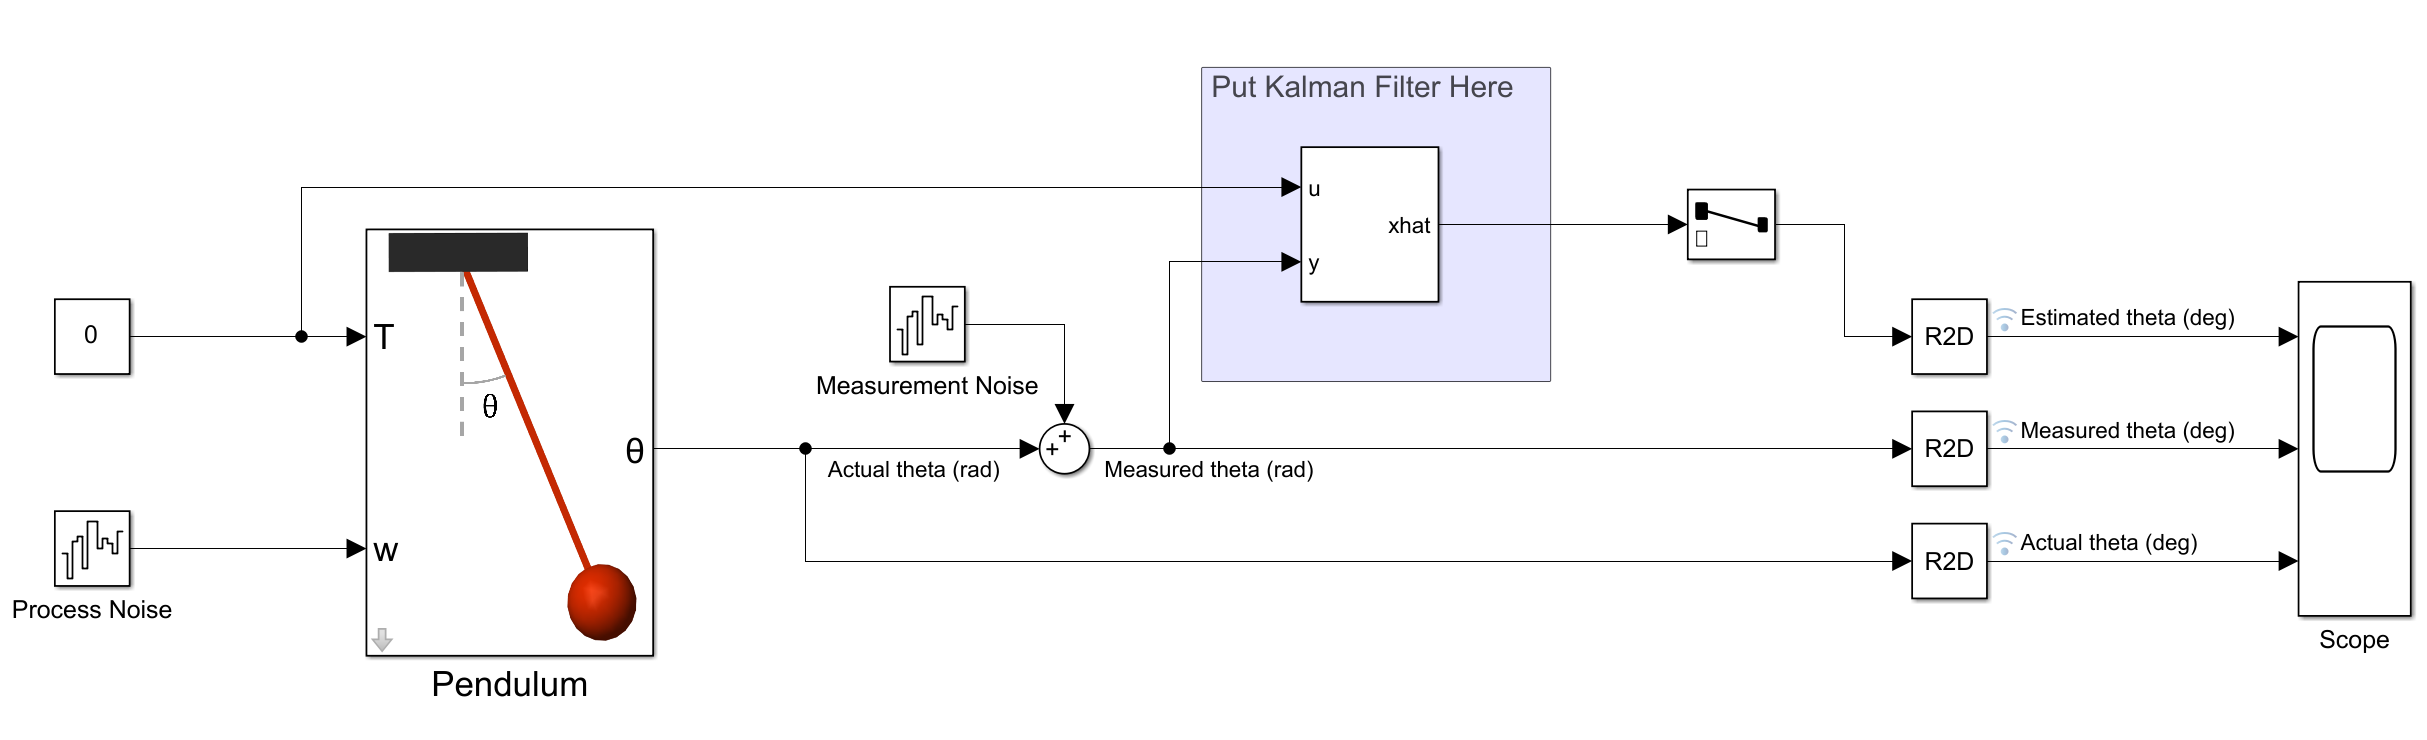

*Simulink model to estimate pendulum's angular position using a linear Kalman filter*

Now that the Kalman filter block is connected to the rest of the model, specify the filter settings in the **Kalman Filter block dialog**.

- Under "Filter Settings", **change the "Time domain" setting to "Continuous-Time"**. 

- Under "Model Parameters" and "System Model", **change the "Model source" setting to "Individual A, B, C, D matrices".** Then replace the **values for A, B, C, and D with the variables** defined earlier in this live script. 

Next, set the Kalman filter parameters. First, **run this section** to define the variables for the initial states given to the Kalman filter, as well as the process noise covariance $Q$ and measurement noise covariance $R$. 

KF_theta0 = theta0; %#ok, used in model
KF_theta_dot0 = theta_dot0;
Q = diag([0, 1e-3]);
R = 1e-4; %#ok, used in model

The process noise covariance $Q$ is a 2x2 diagonal matrix with the diagonal elements corresponding to the expected variance in the states. In the pendulum system, the process noise acts only on the angular acceleration, so the below code sets $Q$ to $\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\ldotp 001
\end{array}\right\rbrack$. And the measurement noise covariance $R$ is set to 1e-4. 

Then, in the **Kalman filter block dialog**:

- Under "Initial Estimates", **set the "Initial states x(0)" to [KF_theta0 KF_theta_dot0]**

- Under "Noise Characteristics", **set "Q" to Q and "R" to R**. We assume no correlation between $Q$ and $R$, so $N$ is 0, which is the default value.  

- **Click OK** to save and close the block dialog.

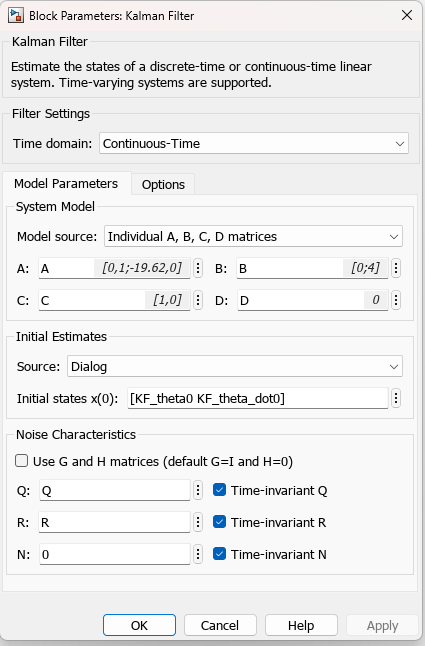

Finally, add some process noise to the simulation. **Run this section** to create a variable $w$ for the process noise. 

w = 1e-5; %#ok, used in model

Then, **double-click the Process Noise block** to open its block dialog. Set the **noise power to w.**

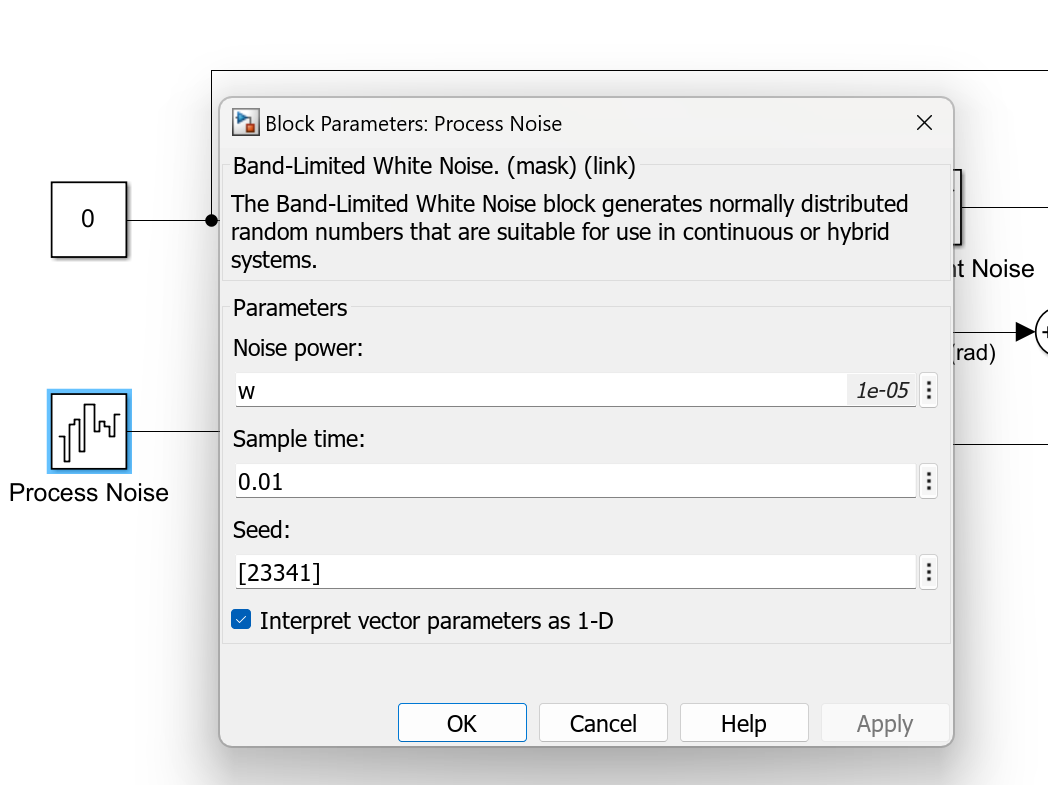

**Run the simulation** to observe actual, measured, and now estimated pendulum responses using the Data Inspector. 

From this point on in the exercise, you can continue working with your own model or choose to use the solution model with the drop-down below.

mdl = "pendulum_model_complete.slx";

You can also run a simulation from a MATLAB script using the [`sim`](https://www.mathworks.com/help/simulink/slref/sim.html) function. 

out = sim(mdl);
figure;
hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
plot(out.logsout.getElement("Estimated theta (deg)").Values,"LineWidth",2,"LineStyle",":","Color","#77AC30");
xlabel('Time [s]'); ylabel('Angular position [°]');
legend("Actual Response","Measured Response","Kalman Filter Estimate","Location","southoutside");
title("Pendulum Motion with Kalman Filter Estimate")
hold off;

Or, you can display saved simulation results in the Data Inspector. After running this section, look for the run named "pendulum_KF" in the Data Inspector.

open("Kf_estimate.mldatx")

### Activity 1: Study Effect of Kalman Filter Initialization

Initialize the Kalman filter with a different value than pendulum's true initial angle **using the slider below**. Each time you change the slider, the model will run and the estimation vs. the actual response will be plotted. Observe how much time it takes the filter to converge the further you move the initial angle the Kalman filter sees from the true initial angle (10 degrees).

KF_theta0 = deg2rad(50);
out = sim(mdl,"StopTime","15");
figure;
hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
plot(out.logsout.getElement("Estimated theta (deg)").Values,"LineWidth",2,"LineStyle",":","Color","#77AC30");
xlabel('Time [s]'); ylabel('Angular position [°]');
legend("Actual Response","Measured Response","Kalman Filter Estimate","Location","southoutside");
title("Pendulum Motion with Kalman Filter Estimate")
subtitle("Kalman Filter Initial Angle = "+string(rad2deg(KF_theta0))+"°"+string(newline)...
        +"Actual Initial Angle = "+string(rad2deg(theta0))+"°");
hold off;

### Activity 2: Determining Measurement Noise Covariance$R$

If prior knowledge of $R$ is not available, it can be estimated using sensor measurements as $R$ represents the noise characteristics of the sensor. To estimate $R$, you can take measurements while the pendulum rests still at 0 degrees and compute the variance of the measured output. **Run this section** to run the simulation and estimation.

theta0 = 0; %#ok, used in model
w = 0; %#ok, used in model
out = sim(mdl,"StopTime","5");
figure;
hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
xlabel('Time [s]'); ylabel('Angular position [°]');
legend("Actual Response","Measured Response","Location","southoutside");
title("Pendulum Motion");
ylim([-15 15])
hold off;
R_estimated = var(deg2rad(out.logsout.getElement("Measured theta (deg)").Values.Data))
diff = abs(1e-4-R_estimated)

The computed variance will be close to previously set value of $R$, 1e-4, as can be seen by the small value of the computed difference above. 

### Activity 3: Effect of Measurement Noise Covariance on Kalman Filter Estimate

Changing the value of the measurement noise covariance will influence whether the Kalman Filter relies more on measurements or the model to make it's estimation. **Use the below drop-down** to set $R$ to different values and observe how Kalman filter behaves.

% Change value of R
R = 1e-7;

% Reset changed parameters back to initial values
theta0 = pi/18;
KF_theta0 = theta0; %#ok, used in model
w = 1e-5;

% Run simulation to see results
out = sim(mdl,"StopTime","10");

figure; tl = tiledlayout(1,3);

% Plot zoomed out
nexttile([1 2]); hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
plot(out.logsout.getElement("Estimated theta (deg)").Values,"LineWidth",2,"LineStyle",":","Color","#77AC30");
rectangle("Position",[1.2 8 0.45 3],"LineWidth",1)
hold off;

% Plot zoomed in
nexttile; hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
plot(out.logsout.getElement("Estimated theta (deg)").Values,"LineWidth",2,"LineStyle",":","Color","#77AC30");
xlim([1.2 1.65]); ylim([8 11])
hold off;

% Titles, Labels, Legend
title(tl,"Pendulum Motion with Kalman Filter Estimate")
subtitle(tl, "R Value = "+compose("%.0e",R));
xlabel(tl,'Time [s]'); ylabel(tl,'Angular position [°]');
lgn = legend("Actual Response","Measured Response","Kalman Filter Estimate");
lgn.Layout.Tile = "south";

You can see the smaller the value of $R$, the more our filter relies on the measurement data. The larger the value of $R$, the more our filter relies on the model. 

### Activity 4: Test Filter Performance for Larger Initial Pendulum Angles

Our Kalman filter uses a linear model that relies on the small angle condition ($\sin \left(\theta \right)~\theta$). **Use the below slider** to run our simulation with different initial angles for the pendulum. 

theta0 = deg2rad(45);   % Specify pendulum's initial angle

KF_theta0 = theta0;  
R = 1e-4;
out = sim(mdl,"StopTime","10");
figure; tl = tiledlayout(2,1);
title(tl,"Pendulum Motion, Initial Angle = "+string(rad2deg(theta0))+" degrees");
xlabel(tl,'Time [s]'); ylabel(tl,'Angular position [°]');
nexttile; hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
plot(out.logsout.getElement("Measured theta (deg)").Values);
plot(out.logsout.getElement("Estimated theta (deg)").Values,"LineWidth",2,"LineStyle",":","Color","#77AC30");
legend("Actual Response","Measured Response","Kalman Filter Estimate","Location","eastoutside");
title("With Kalman Filter Estimate"); hold off;
nexttile; hold on;
plot(out.logsout.getElement("Actual theta (deg)").Values,"LineWidth",2);
[poslin,tlin] = initial(ss(A,B,C,D),[theta0;0],10);
plot(tlin,rad2deg(poslin),"LineWidth",2,"Color","#4DBEEE")
legend("Actual Response","Linearized Model","Location","eastoutside");
title("Nonlinear vs. Linearized Model"); hold off;

As the initial angle deviates further from small angles, our linear Kalman filter becomes less and less accurate. In the [next exercise](matlab:open('ExtendedKalmanFilterExercise.mlx')), we'll explore Kalman filters that use nonlinear models.